clear all
clc
clf
close all

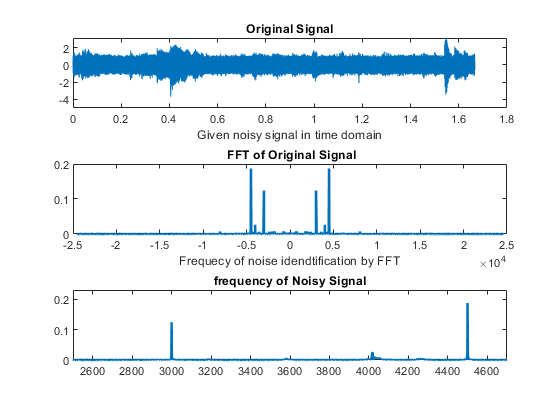

load('noisysignal.mat')
sound(x) %origina sound

noisy=x;
fs=49152;

N=length(x);
L=2^nextpow2(N);
t=(0:N-1)/fs;

subplot(3,1,1)
plot(t,x)
title('Original Signal')
xlabel('Given noisy signal in time domain')
subplot(3,1,2)
X1=abs(fftshift(fft(x,L)/L));
fn=fs/L;
f=-fs/2:fn:fs/2-fn;
plot(f,X1,'linewidth',2)
title(' FFT of Original Signal');
xlabel('Frequecy of noise idendtification by FFT')
subplot(3,1,3)
plot(f,X1,'linewidth',2)
axis([2500 4700,0 .23])
title('frequency of Noisy Signal'); % 3000Hz and 4500 Hz are noisy signal

Design first filter

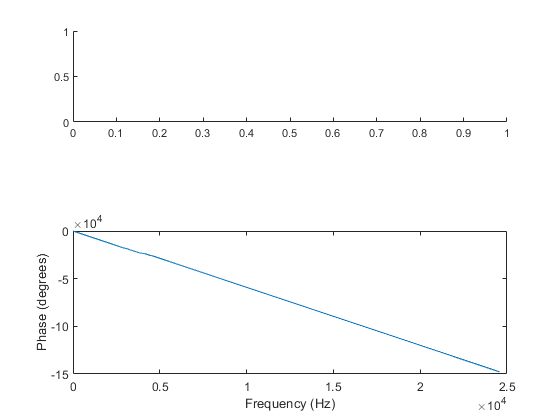

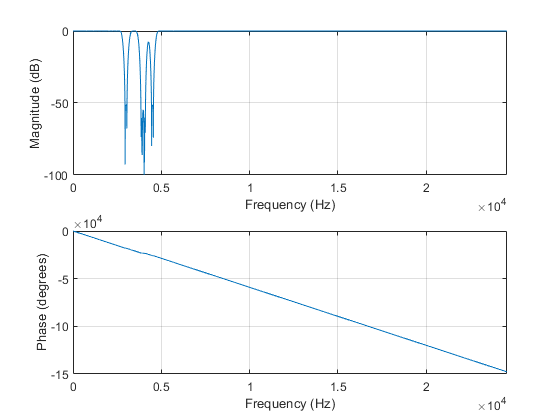

order=554;
fs1=49152;
wg1 = [4300*2/fs1, 4700*2/fs1];
%[b1,a1] = butter(3,wg1,'stop');
[b1,a1] =fir1(order,wg1,'DC-1',hamming(order+1));

% Design second filter
wg2 = [2800.0*2/fs1, 3200.5*2/fs1];
%[b2,a2] = butter(3,wg2,'stop');
[b2,a2] =fir1(order,wg2,'DC-1',hamming(order+1));
%design Third order
fs1=49152;
wg3 = [3700*2/fs1, 4250.0*2/fs1];
%[b3,a3] = butter(3,wg3,'stop');
[b3,a3] =fir1(order,wg3,'DC-1',hamming(order+1));
% Convolve filters
a0 = conv(a1, a2);
b0 = conv(b1, b2);
a11 = conv(a0, a3);
b11 = conv(b0, b3);
a0=a11;
b0=b11;
% Plot filter
subplot(2,1,2);
title('Designed Filter');
freqz(b0, a0, 4096, fs1);

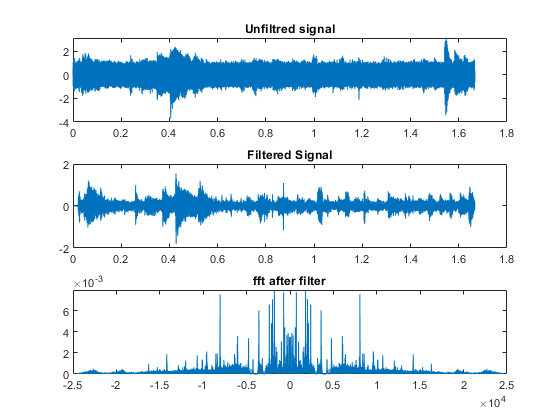

without_nois= (filter(b0,a0,x));
without_nois2=filter(b3,a3, (without_nois));

y=without_nois2;
L2=2^nextpow2(length(y));
Y=abs(fftshift(fft(y,L2)/L2));
fn=fs/L2;
figure(3)
f=-fs/2:fn:fs/2-fn;
subplot(3,1,1)
plot(t,x)
title('Unfiltred signal')
subplot(3,1,2)
plot(t,y)
title('Filtered Signal')
subplot(3,1,3)
plot(f,Y)
title('fft after filter');

disp("After the noisy sound, Press any Key to listen filtered Sound")

After the noisy sound, Press any Key to listen filtered Sound


pause
sound(without_nois2)%filtered sound

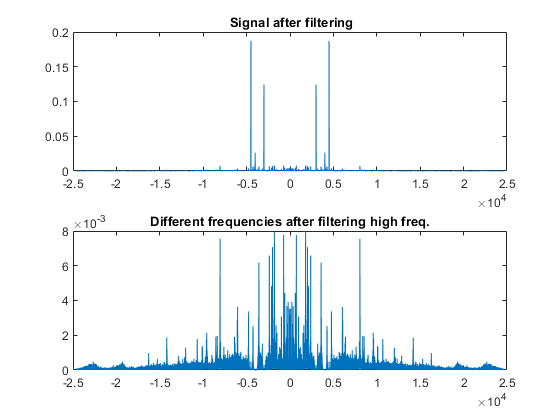

xx=without_nois;
fs=49152;

t=(0:length(xx)-1)/fs;
L=length(xx);

N=2^nextpow2(L);
X=abs(fftshift(fft( (xx),N)/N));

fn=fs/N;

figure(2)
f=-fs/2:fn:fs/2-fn;

subplot(2,1,1)
plot(f,X1)
title(' Signal after filtering')

subplot(2,1,2)
plot(f,X)
title('Different frequencies after filtering high freq.');

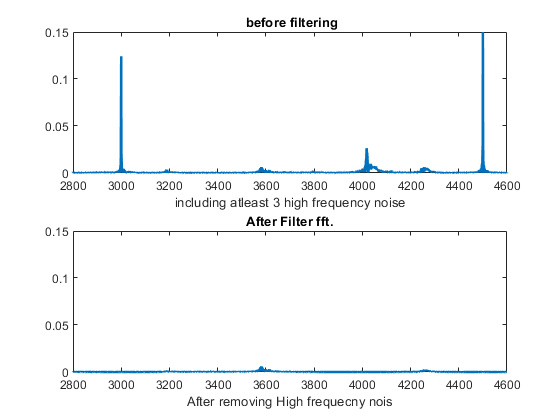

figure(4)
title('comparision of Filtering')
%comparing
subplot(2,1,1)
plot(f,X1,'linewidth',2)
title(' before filtering')
axis([2800 4600,0 0.15])
xlabel('including atleast 3 high frequency noise')

subplot(2,1,2)
plot(f,X,'linewidth',2)
title('After Filter fft.');
axis([2800 4600,0 0.15])
xlabel('After removing High frequecny nois')